Daniel Sklyar

Homework #4

a)

    Newtons divided differences function is in the function block.

b)

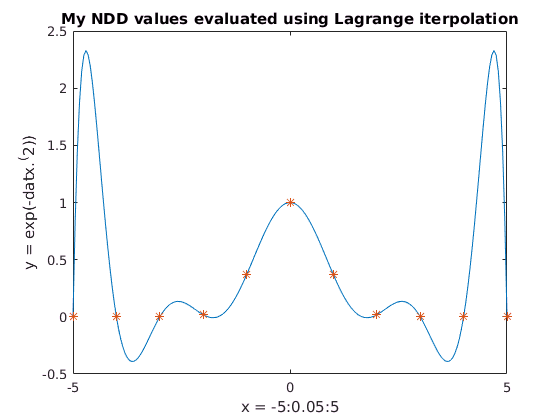

x = -5:0.05:5;
datx = -5:1:5;
daty = exp(-datx.^(2));
y = newtons_divided_differences(x,datx,daty);

size(y)

ans =     11    11


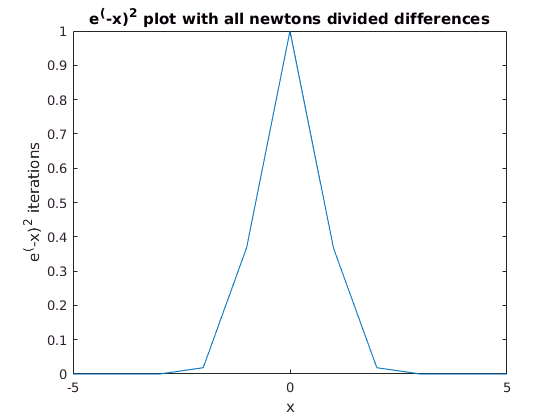

figure(1)
plot(datx,y(:,1)), hold on;
title('e^(-x)^2 plot with all newtons divided differences');
ylabel('e^(-x)^2 iterations');
xlabel('x')
hold off;

c)

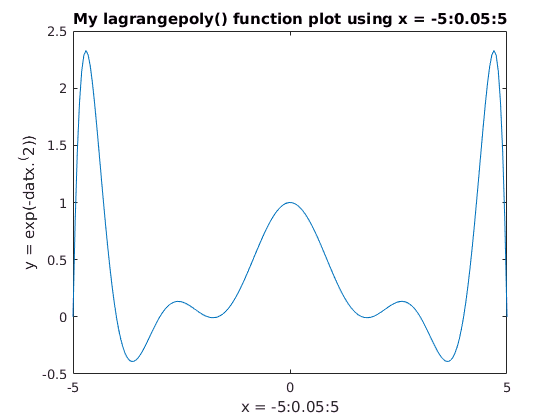

x = -5:0.05:5;
datx = -5:1:5;
daty = exp(-datx.^(2));
y = lagrange_poly(x,datx,daty);
figure(2)
plot(x,y), hold on;
title('My lagrangepoly() function plot using x = -5:0.05:5');
ylabel('y = exp(-datx.^(2))');
xlabel('x = -5:0.05:5');
hold off;

Result is similar with my lagrangepolynomial finction from hmk3

function y = newtons_divided_differences(x,datx,daty)
    n = size(datx,2) - 1;      % get the size of data points in datx 
    y = zeros(n+1,n+1);        % create output matrix [n + 1, n + 1]
    y(:,1) = daty;
    % book psuedo code
    for i=1:n
        for j=1:i
            y(i+1,j+1) = (y(i+1,j)-y(i,j)) / (datx(i+1)-datx(i-j+1));
        end
    end
    % ploting using data aquired
    a = diag(y);                            % get diagonal elements using matlab func
    ploty = a(n+1)*ones(size(x));           % evaluate the value of the Lagrange iterpolation
    for i=n:(-1):1                          % start from n, decrement by 1, until 1
        ploty = a(i) + ploty.*(x-datx(i));  % calculate the y point
    end
    figure(1);
    plot(x, ploty, '-', datx, daty, '*'), hold on;
    title('My NDD values evaluated using Lagrange iterpolation');
    ylabel('y = exp(-datx.^(2))');
    xlabel('x = -5:0.05:5');
    hold off;
end
function [sol] = lagrange_poly(x,datx,daty)
    sol = 0;                            % set return value [sol] to zero
    num = size(datx,2);                 % get length of datx array
    mat = ones(num,size(x,2));          % generate matrix size(datx,2) X size(daty,2)
                                        % using ones() in order to multiply 1*newval
    for i = 1:num                       % loop 1 tru colms
        for j = 1:num                   % loop 2 tru rows
            if i ~= j                   % if x_i != x_j
                % mat(i,:) -> all elements in the ith row 
                % (x - x_j) / (f(x_i) - f(x_j)) with [num] as degree
                mat(i,:) = mat(i,:).*(x - datx(j))./(datx(i)-datx(j));
            end
        end
    end
    for i = 1:num
        %Multiply Ln polynomials by the f(xn) given by [daty] and xn by [datx]
        sol = sol + daty(i) .* mat(i,:);
    end
end